# **pPCA**

**Model:**


$$X=W\cdot Z+\epsilon$$


- $X$: Data in High dimension

- $Z$: $X$ projected to Low dimension

- $W$: Linear Transformation Matrix

- $\epsilon$ : noise

**Constrain:**

- $X$: gaussian distribution

- $Z$: gaussian distribution with $\textrm{mean}\left(Z\right)=0$ and $\textrm{cov}\left(Z\right)=I$

- $\epsilon$: gaussian distribution with $\textrm{mean}\left(\epsilon \right)=0$ and $\textrm{cov}\left(Z\right)=I\cdot s_0$

**Goal: **find Linear Transformation Matrix $W$

### Create Data

clc; clear
[u,~,~] = svd(rand(3,4),'econ');
S = diag(rand(3,1)*10)+eye(3)*0.5;
X = u*S*randn(3,1000);
X = X + randn(size(X))/100;

### pPCA

W0 = rand(3,2);
s0 = 0.1;
[W, mu, para] = ppca_em(X, 2, 1e-6, 1000,W0,s0);

**Project to 2D**

Z_2d = W\ (X-mean(X,2));

**Check Projection Cov Matrix (expect close to I)**

sig = Z_2d*Z_2d'/size(Z_2d,2)

sig =     1.0190    0.0134
    0.0134    1.0255


**Plot Log Likelihood**

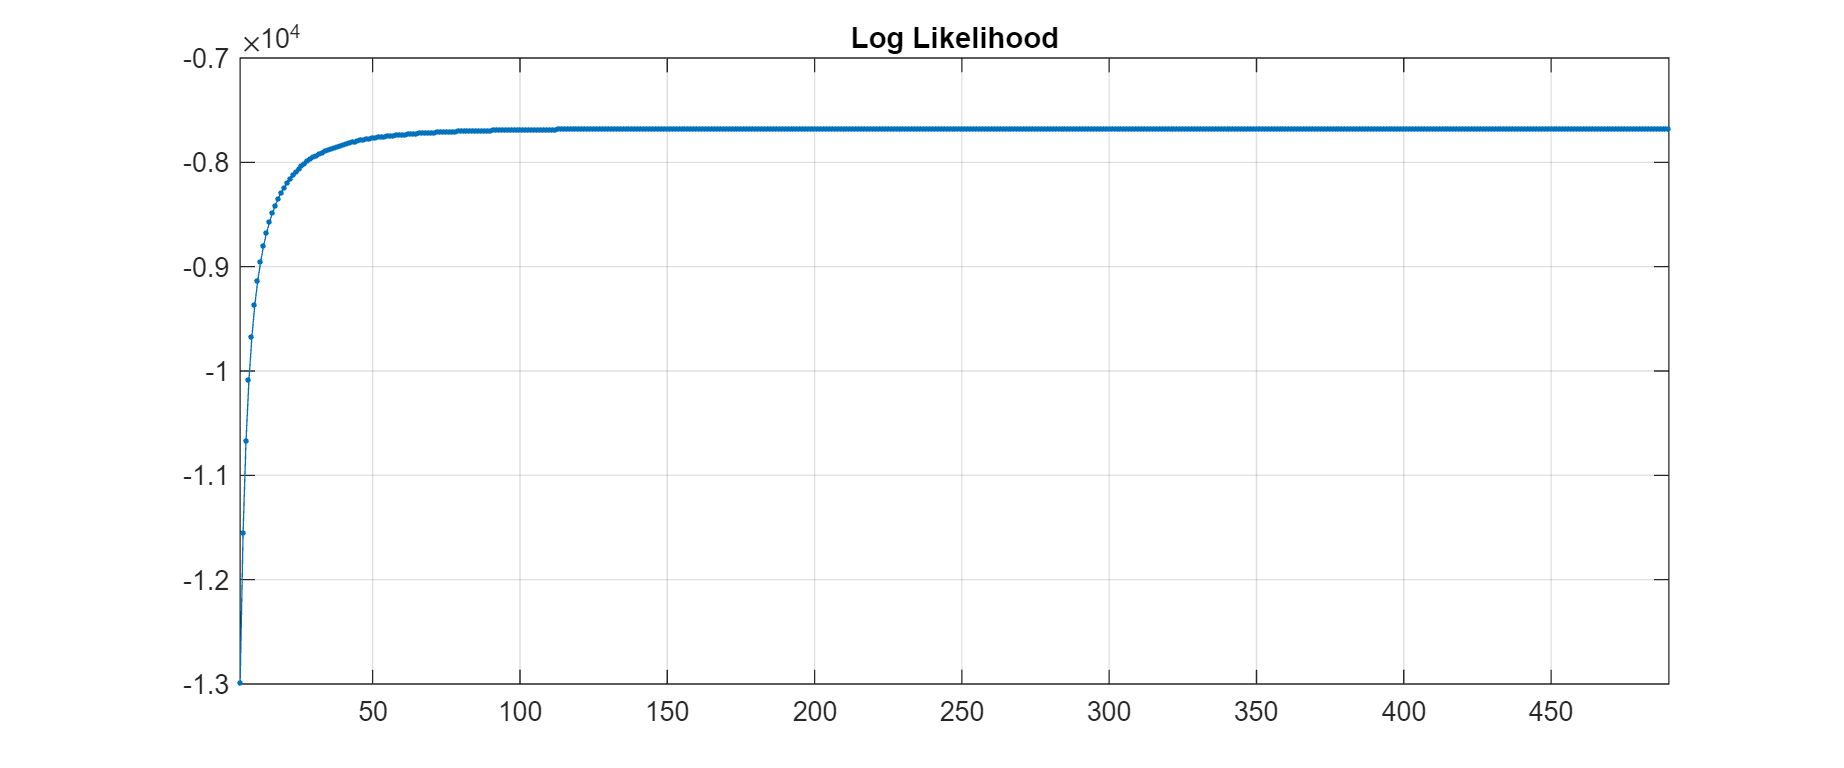

f = figure;
plot(5:para.iter,para.loglk_all(5:end),'.-'); 
grid on; title('Log Likelihood')
xlim([5,para.iter])
set(f,'Units','normalized','Position',[0,0,0.6,0.4])

### **Plot pPCA Axis**

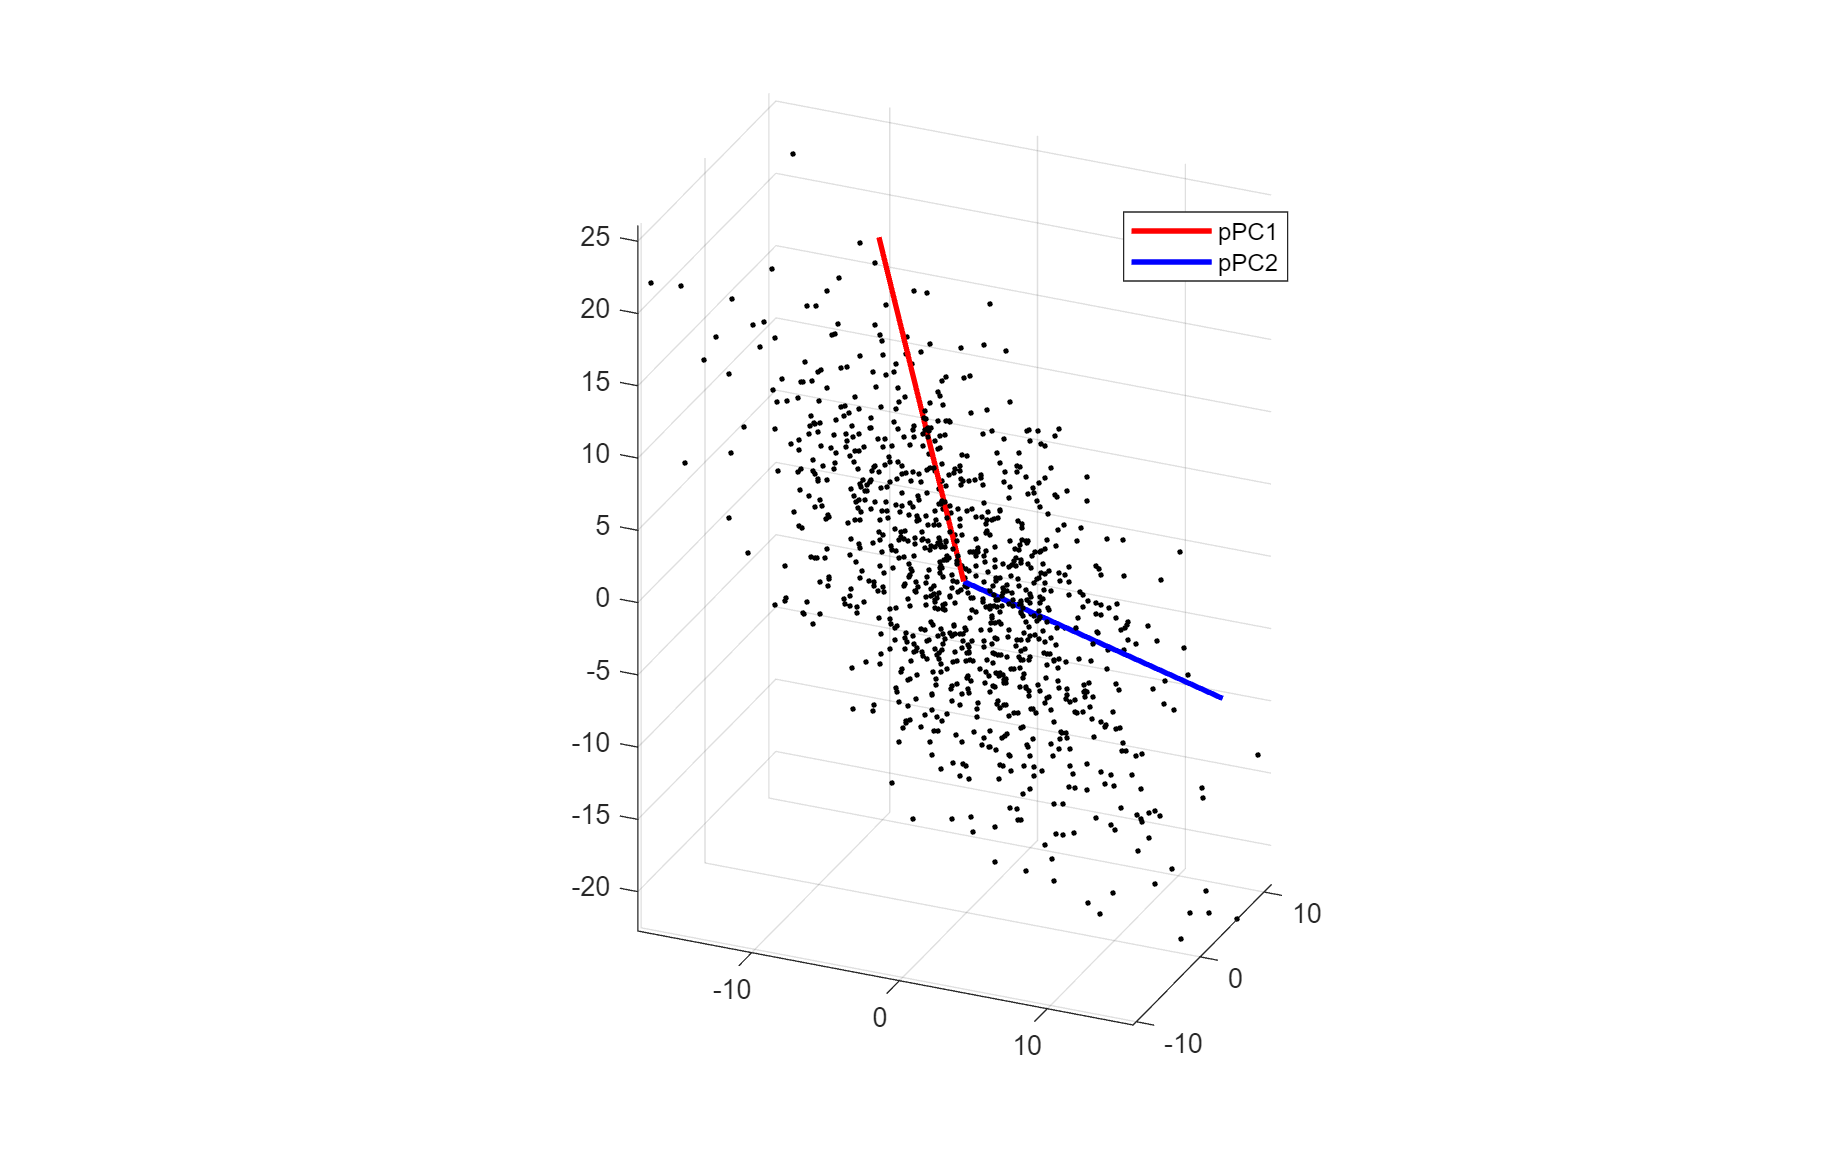

ppc1 = [zeros(3,1),W(:,1)]*3 + mu;
ppc2 = [zeros(3,2),W(:,2)]*3 + mu;

f = figure;
plot3(X(1,:),X(2,:),X(3,:),'.k'); hold on
p2 = plot3(ppc1(1,:),ppc1(2,:),ppc1(3,:),'-r','LineWidth',2); hold on
p3 = plot3(ppc2(1,:),ppc2(2,:),ppc2(3,:),'-b','LineWidth',2); hold on
grid on; axis equal
legend([p2,p3],{'pPC1','pPC2'})
set(f,'Units','normalized','Position',[0,0,0.6,0.6])

### Plot 2D Projection

We expect Z is zero mean and Cov=1

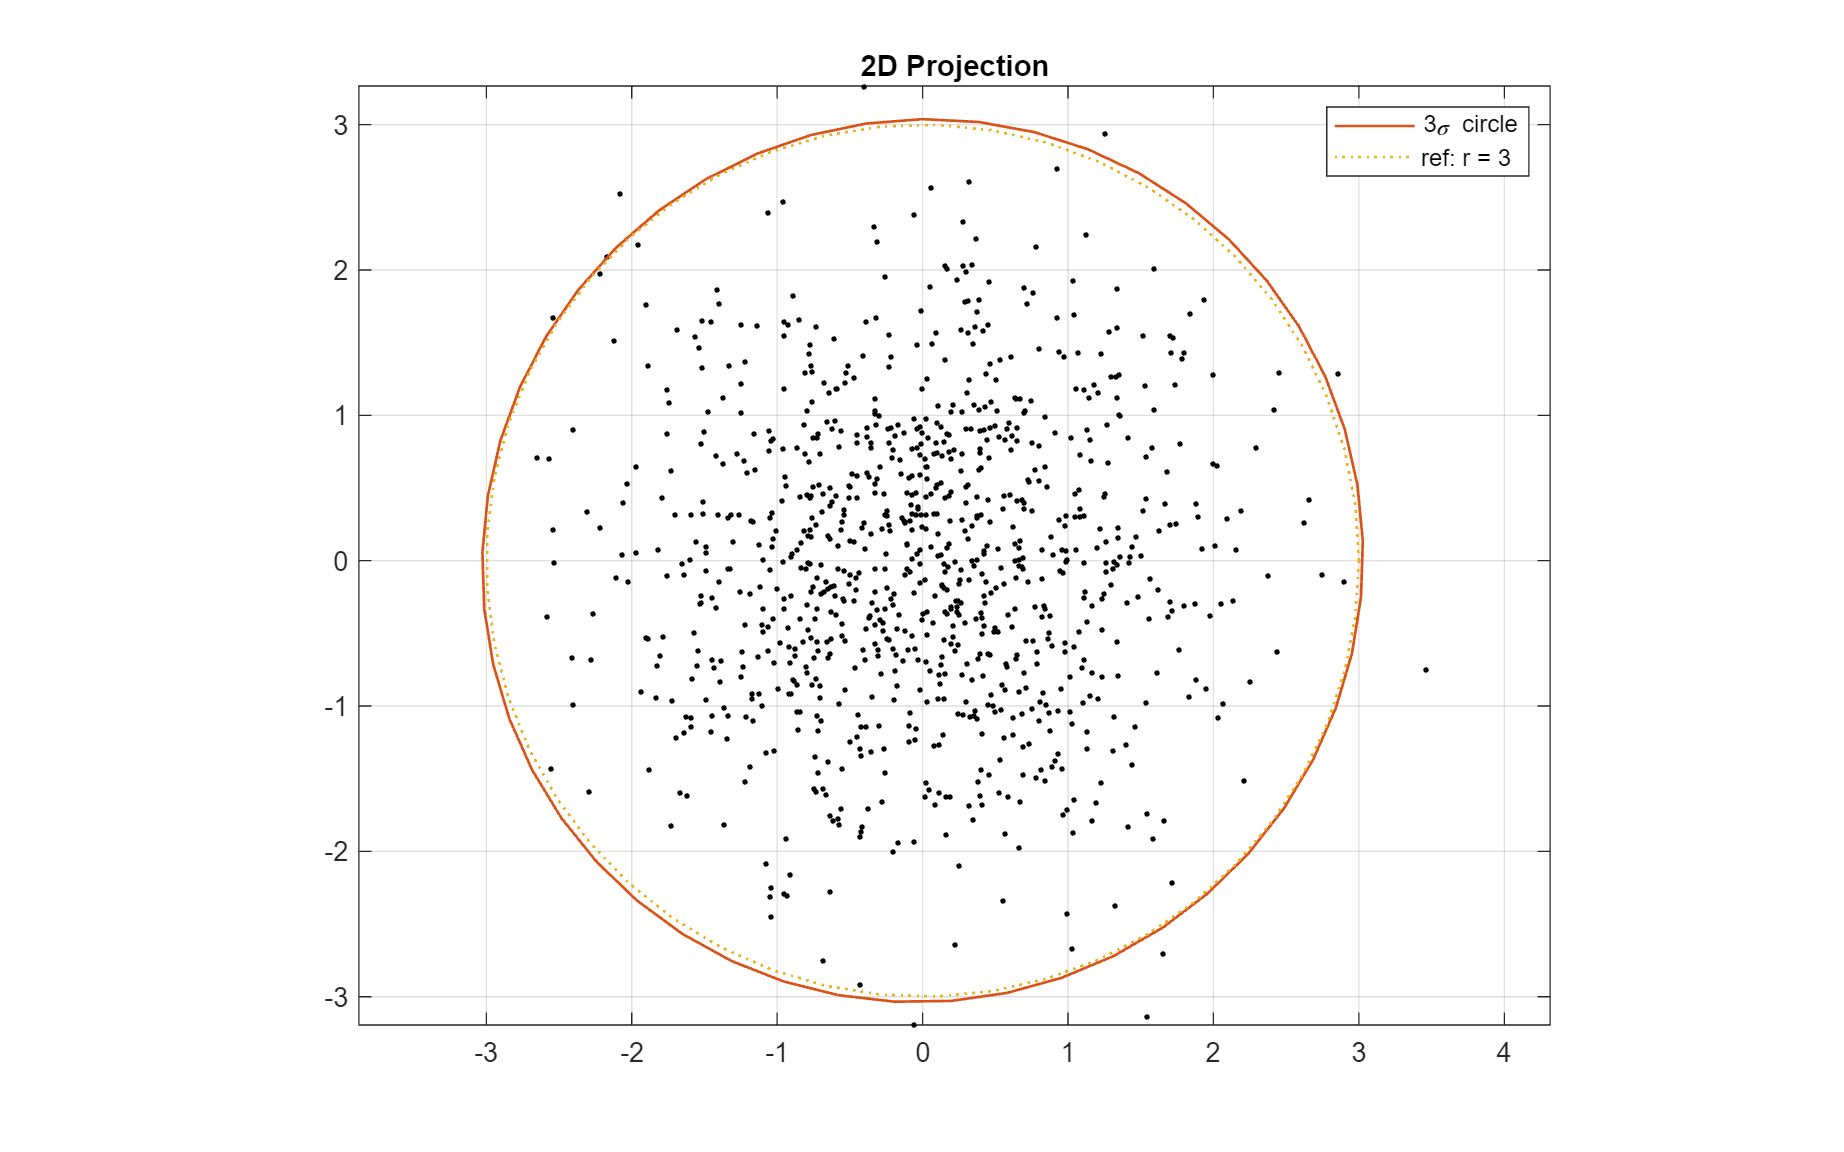

elip = cov2ellip(sig,3,mean(Z_2d,2),50); % 3 sigma circle, I expect it close to r = 3
elip_ref = cov2ellip(eye(2),3,[0;0],50);

f = figure;
plot(Z_2d(1, :), Z_2d(2, :), '.k'); hold on
p2 = plot(elip(1,:),elip(2,:),'-','LineWidth',1); hold on
p3 = plot(elip_ref(1,:),elip_ref(2,:),':','LineWidth',1); hold on
grid on; axis equal; title('2D Projection')
legend([p2,p3],{'3\sigma circle','ref: r = 3'})
set(f,'Units','normalized','Position',[0,0,0.6,0.6])